# MECHENG 4K03: A2 - suitorj - 400138679

## Setup

sympref('AbbreviateOutput', false);

## Question 1

- Done

- $\left\lbrack \begin{array}{ccccc}
n+1 & \theta  & d & a & \alpha \\
1 & 0 & 0 & L_1  & 0\\
2 & \theta_1  & 0 & 0 & -90\\
3 & 0 & L_2  & 0 & 0
\end{array}\right\rbrack$ The joint variables are $L_1$, $\theta_1$.

- 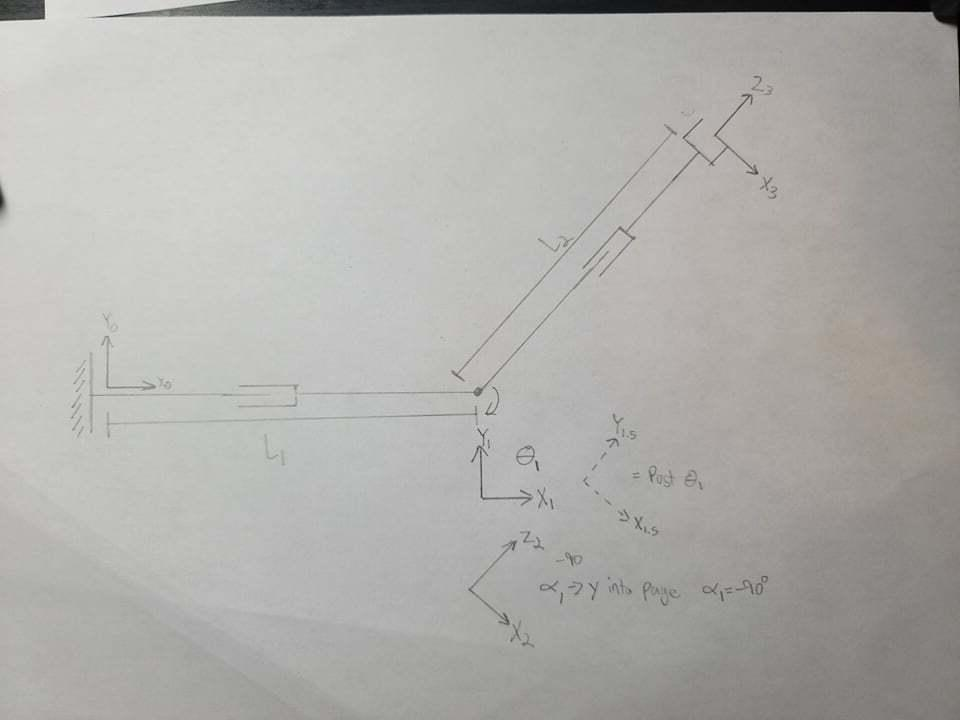

syms L1 L2 theta1
A1 = create_identity(4) * translate_frame([L1 0 0]) 

$$A1 = \left(\begin{array}{cccc} 1 & 0 & 0 & L_{1}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A2 = rotate('Z', theta1) * rotate('X', -90) 

$$A2 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & 0 & \cos\left(\theta_{1}\right) & 0\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A3 = translate_frame([0 0 L2])

$$A3 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & L_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T = simplify(A1* A2 * A3)

$$T = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & L_{1}-L_{2}\,\sin\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & 0 & \cos\left(\theta_{1}\right) & L_{2}\,\cos\left(\theta_{1}\right)\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Question 2

- Done

-  $\left\lbrack \begin{array}{ccccc}
n+1 & \theta  & d & a & \alpha \\
1 & \theta_1  & 0 & L_1  & 0\\
2 & \theta_2  & 0 & L_2  & 0\\
3 & \theta_3  & 0 & L_3  & 0
\end{array}\right\rbrack$The joint variables are $\theta_1$, $\theta_2$, $\theta_3$.

- 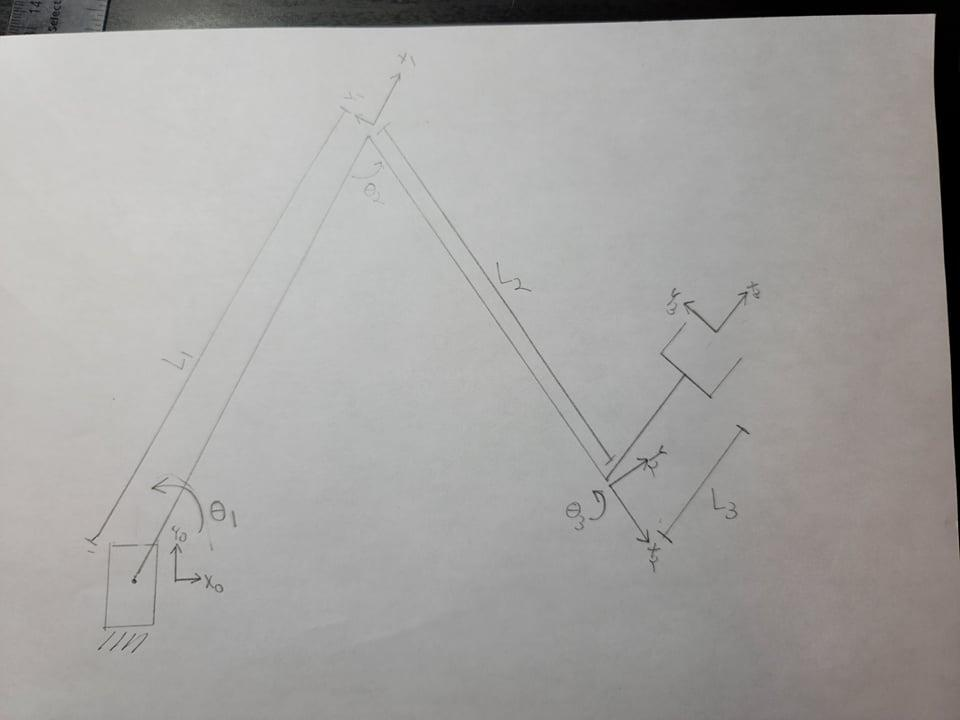

syms theta1 theta2 theta3 L1 L2 L3
A1 = create_identity(4) * rotate('Z', theta1) * translate_frame([L1 0 0]) 
A2 = create_identity(4) * rotate('Z', theta2) * translate_frame([L2 0 0]) 
A3 = create_identity(4) * rotate('Z', theta3) * translate_frame([L3 0 0]) 

$$A1 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & L_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & L_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T = simplify(A1* A2 * A3);

$$A2 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & L_{2}\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & L_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$A3 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & L_{3}\,\cos\left(\theta_{3}\right)\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & L_{3}\,\sin\left(\theta_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T = \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) & -\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right) & 0 & L_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\cos\left(\theta_{1}\right)+L_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right) & \cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) & 0 & L_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\sin\left(\theta_{1}\right)+L_{3}\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$